# Projeto de Controlador PI

# Boas práticas

clear all;          % limpa as variáveis
clc;                % limpa a tela
close all;          % fecha as figuras abertas


% Example:
% [vel,pos,entrada] = importfile('exp7.txt',1, 4685);

## Importando dados

[Omega,Theta,Entrada] = ImportaDados('exp7.txt',1, 4685);

% Omega - velocidade
% Theta -  posição
% Entrada

%%% Especificando o tempo - eixo x

Ts    = 1e-3;                       % taxa de amostargem do sistema de aquisição - 1ms
tempo = linspace(0,4685*Ts,4685);   % vetor tempo para análise dos sinais


## Visualizando dados

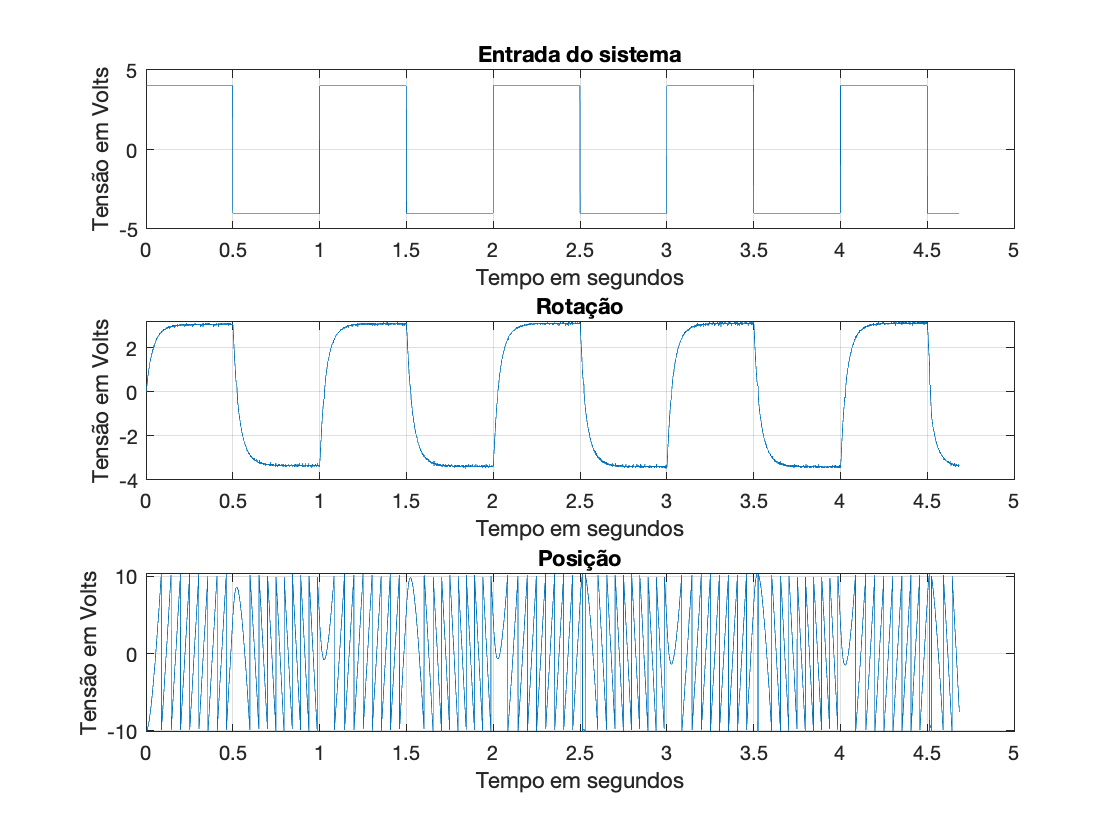

figure(1)

subplot(3,1,1)
plot(tempo,Entrada);
title('Entrada do sistema');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

subplot(3,1,2)
plot(tempo,Omega);
title('Rotação');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

subplot(3,1,3)
plot(tempo,Theta);
title('Posição');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

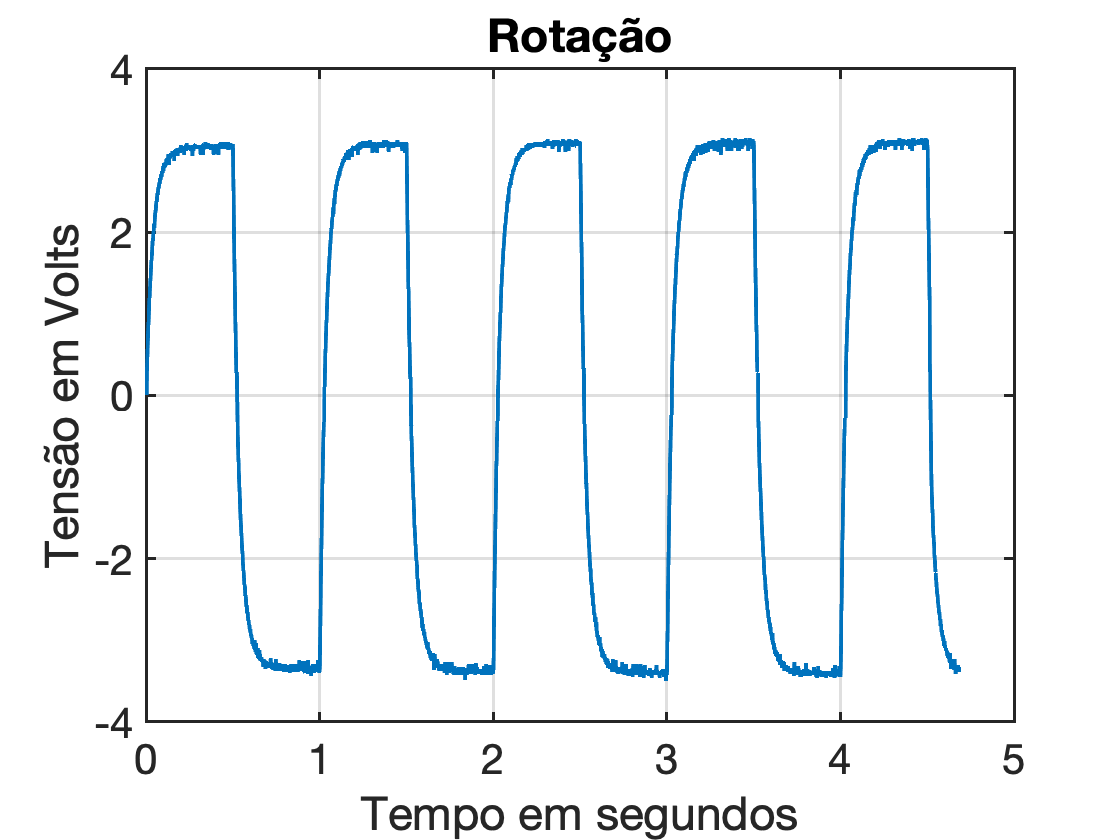

figure()

plot(tempo,Omega);
title('Rotação');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

 set(findall(gcf,'Type','line'),'LineWidth',2);
 set(gca,'FontSize',21,'LineWidth',1.5);

## Análise dos sinais no domínio de Laplace

O sinal de entrada $U(s)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega(s)$. Logo a relação entre entrada e saída é dada pela função de transferência:

$\frac{\Omega(s)}{U(s)} =  \frac{K_m}{s+p_m}$ . Neste caso supomos ser de primera ordem pelo aspecto geral do sinal **Rotação**.

 Gp = tf(20,[1 15])

Gp =
 
    20
  ------
  s + 15
 
Continuous-time transfer function.



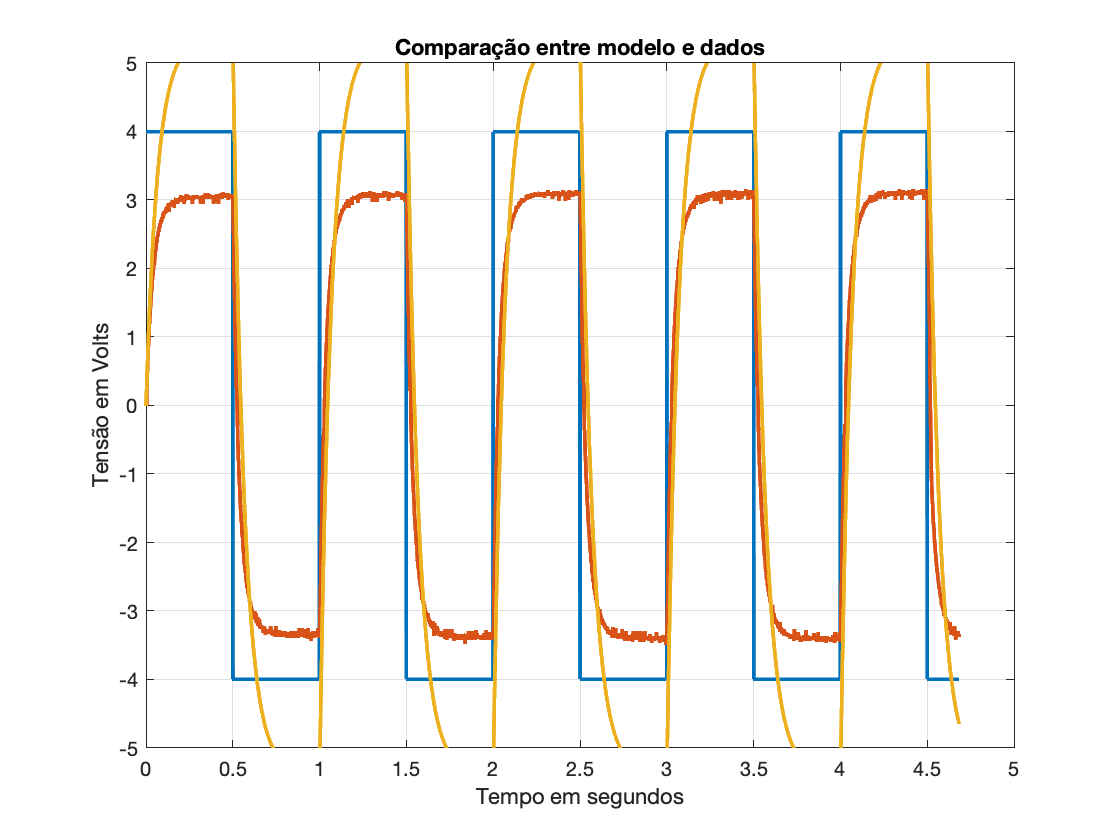

ym = lsim(Gp,Entrada,tempo);                                    % saída do modelo para a mesma entrada
figure(2)
plot(tempo,Entrada, tempo,Omega, tempo,ym, "LineWidth",2);
axis([0 5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

## Ajustando os parâmetros do modelo

x0 = [1 1];                 % condição inicial Km = 1 e pm = 1

X = fminsearch(@(x) ErroQuadratico(x,Entrada,Omega,tempo') ,x0) 

X =    22.4732   28.0882


## Verificando o resultado

Gp = tf(X(1),[1 X(2)])                      % função de transferência do modelo Km =  X(1)  e pm = X(2)

Gp =
 
    22.47
  ---------
  s + 28.09
 
Continuous-time transfer function.



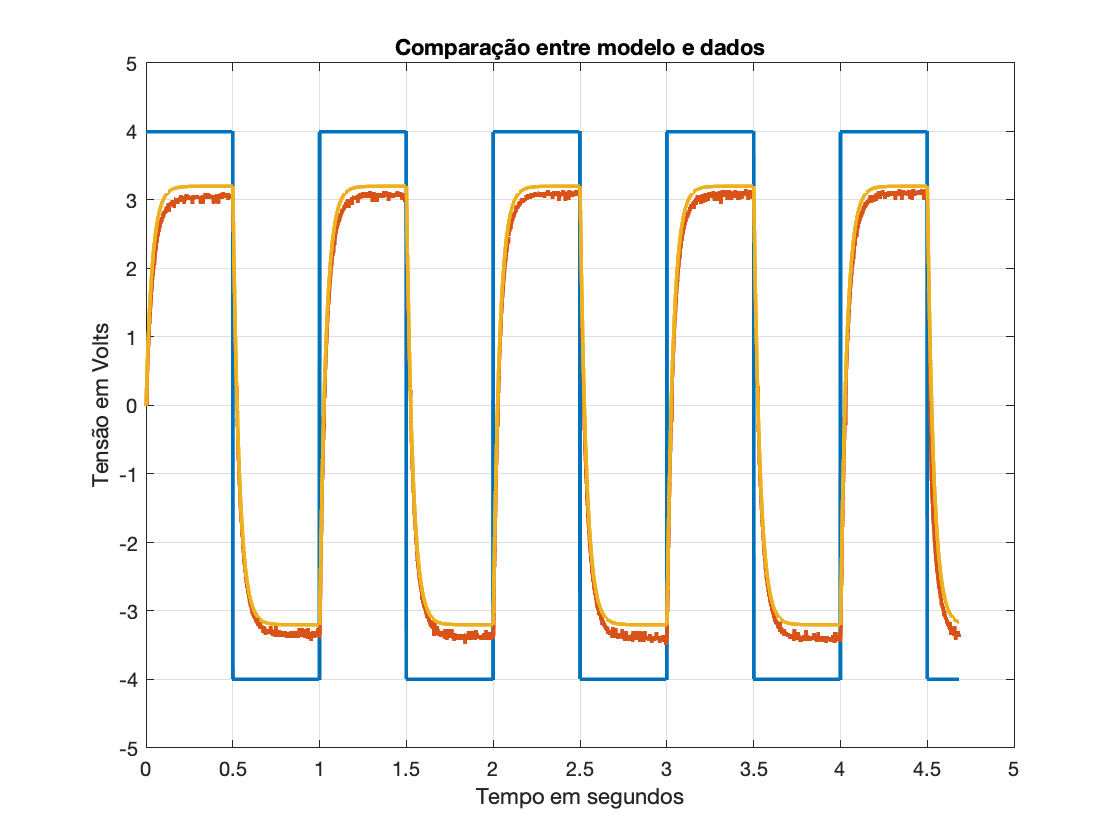


ym = lsim(Gp,Entrada,tempo);                % saída do modelo
figure(2)
plot(tempo,Entrada, tempo,Omega, tempo,ym, "LineWidth",2);
axis([0 5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

## Sintonizando um controlador proporcional

%%% Estimando o tempo de acomodação 
%%% Obtendo o polo da função de tranferência

den  = Gp.Denominator;         % resulta em um array do tipo cell

den  = cell2mat(den);        % converte para manipulação direta

polo = roots(den);             % determina as raizes

Ts   =  4/polo(1);             % estimativa a partir do critério de 2%

%%% Determinando o tempo de acomodação critério de 2%
%%% abordagem computacional

%%% Extraindo um dos trechos dos dados

ti = max(find(tempo<0.5));

t1 = tempo(1:ti);
y1 = Omega(1:ti);

%%% Estima o valor final da saída real

Vf  =  mean(y1(end-50:end));

Ti = min(find(y1>0.98*Vf))

Ti = 163

Ts = t1(Ti)             % determinação do tempo de aocmodação

Ts = 0.1620

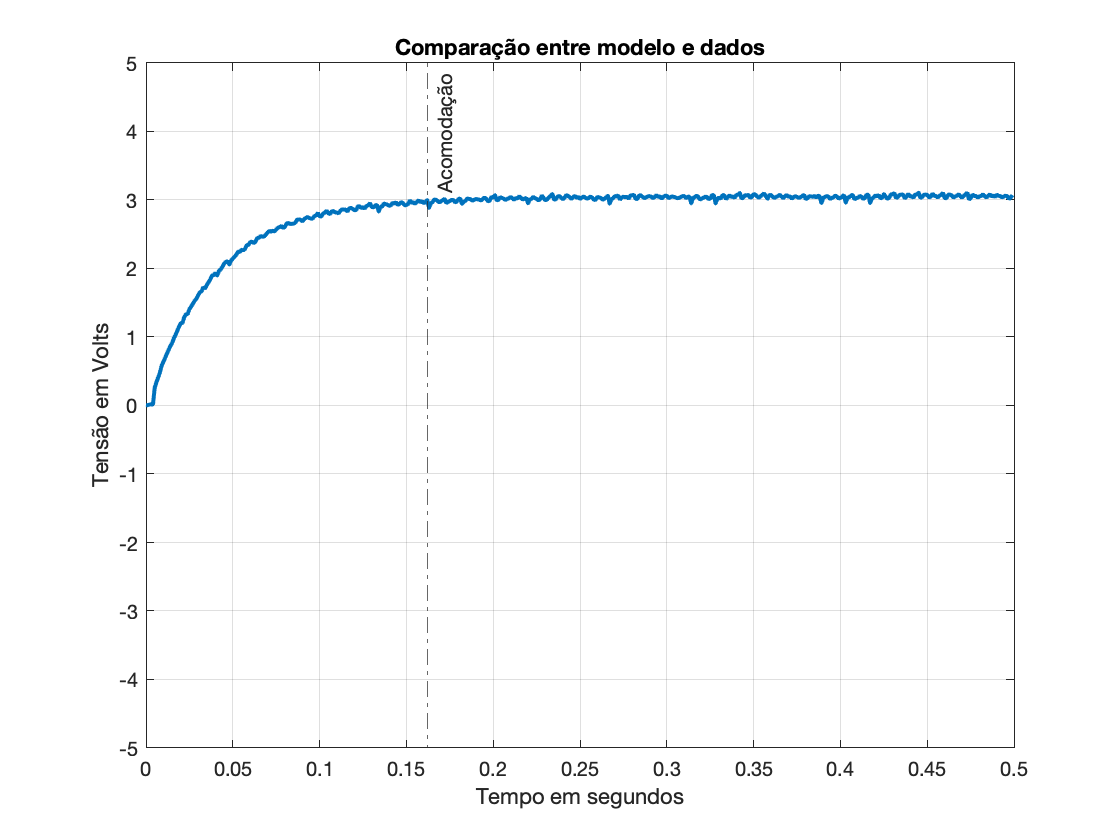

figure(3)
plot(t1,y1, "LineWidth",2);
axis([0 0.5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;
xline(Ts,'-.','Acomodação')

## Implementando o controlado proporcional

GMF = feedback(0.53*Gp,1)           % determina a função em malha fechada

GMF =
 
  11.91
  ------
  s + 40
 
Continuous-time transfer function.



Current plot held


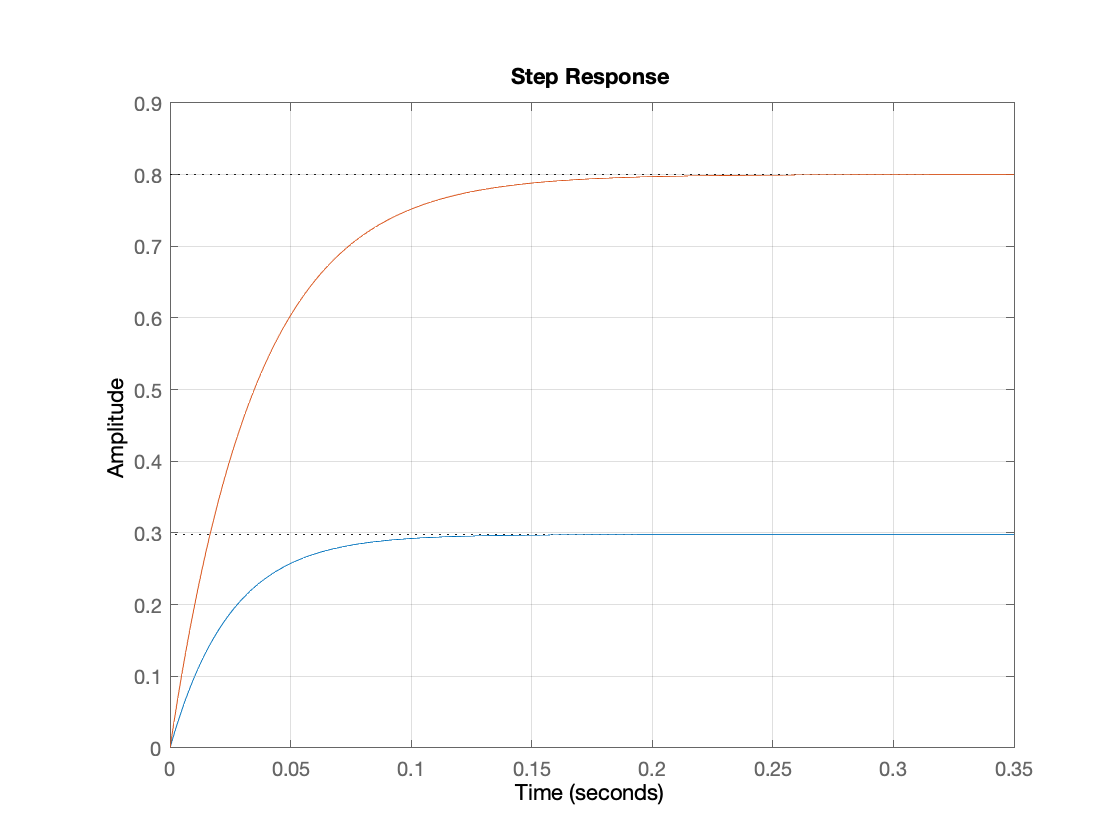

step(GMF); hold; step(Gp);grid

## Analisando em malha fechada

Gmf   = feedback(0.53*Gp,1)           % saída y(t)

Gmf =
 
  11.91
  ------
  s + 40
 
Continuous-time transfer function.



Gesf  = feedback(0.53,Gp)             % esforço de controle

Gesf =
 
  0.53 s + 14.89
  --------------
      s + 40
 
Continuous-time transfer function.



Gerro = feedback(1,0.53*Gp)           % erro   

Gerro =
 
  s + 28.09
  ---------
   s + 40
 
Continuous-time transfer function.



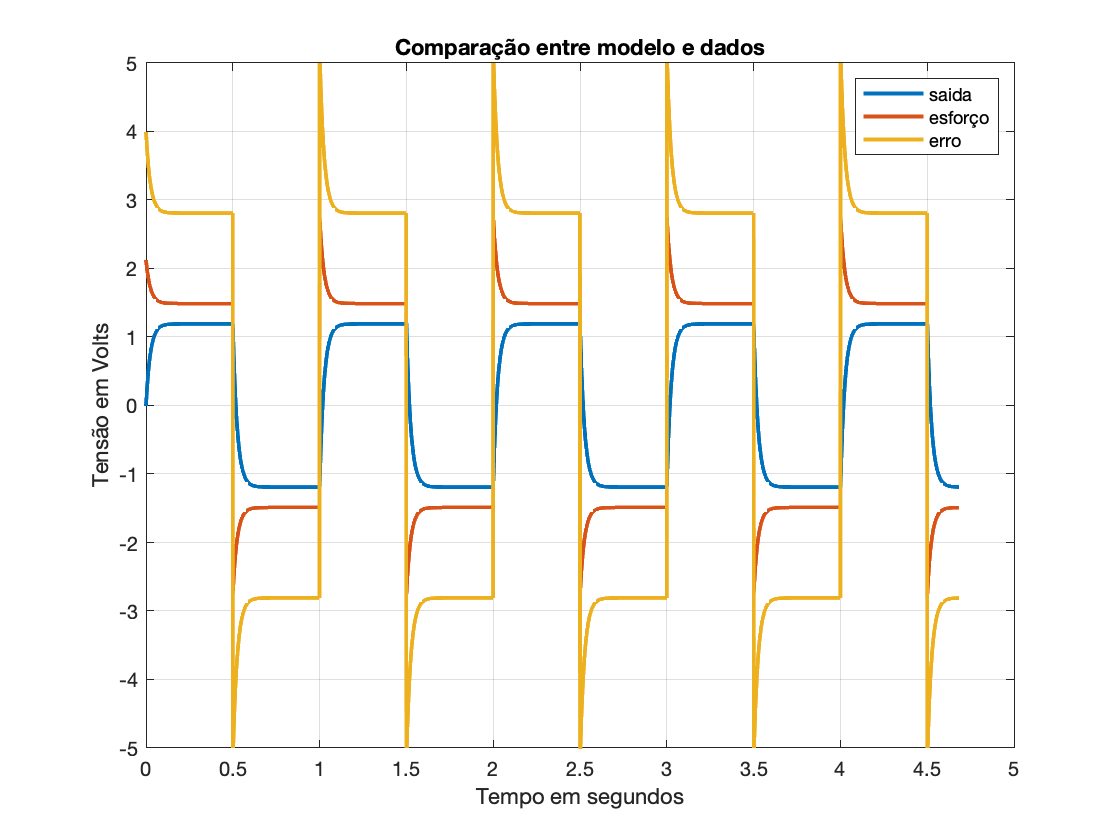


ymf = lsim(Gmf,Entrada,tempo);            % saída no tempo
u = lsim(Gesf,Entrada,tempo);           % esforço de controle no tempo
e = lsim(Gerro,Entrada,tempo);          % erro no tempo

figure()
plot(tempo,ymf, tempo,u, tempo,e, "LineWidth",2);
axis([0 5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid; legend('saida','esforço','erro')

## Projeto de um controlador integral

Ki  =  1;
Gc  =  tf(Ki,[1 0])

Gc =
 
  1
  -
  s
 
Continuous-time transfer function.



Gmf  =  feedback(Gc*Gp,1)

Gmf =
 
          22.47
  ---------------------
  s^2 + 28.09 s + 22.47
 
Continuous-time transfer function.



D  = Gmf.Denominator

D = 1×1 cell array
    {1×3 double}


D  =  cell2mat(D)

D =     1.0000   28.0882   22.4732



Polos = roots(D)

Polos =   -27.2640
   -0.8243


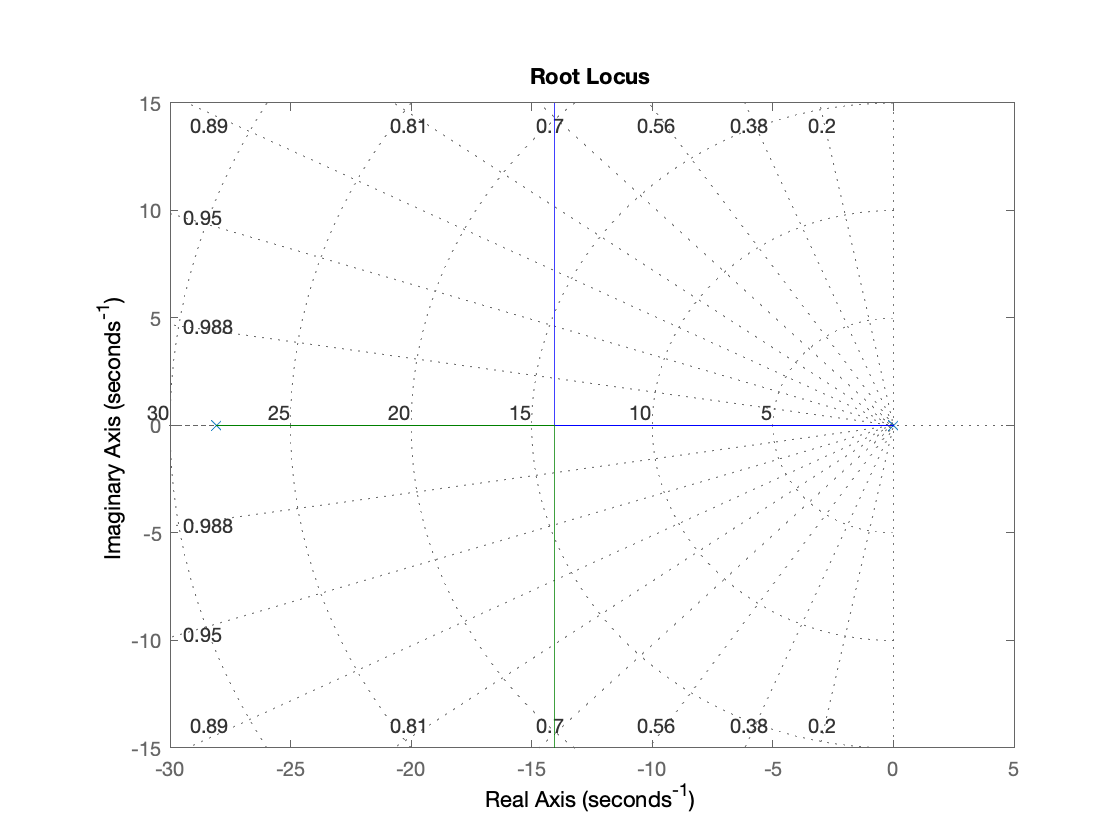

rlocus(Gc*Gp)
grid

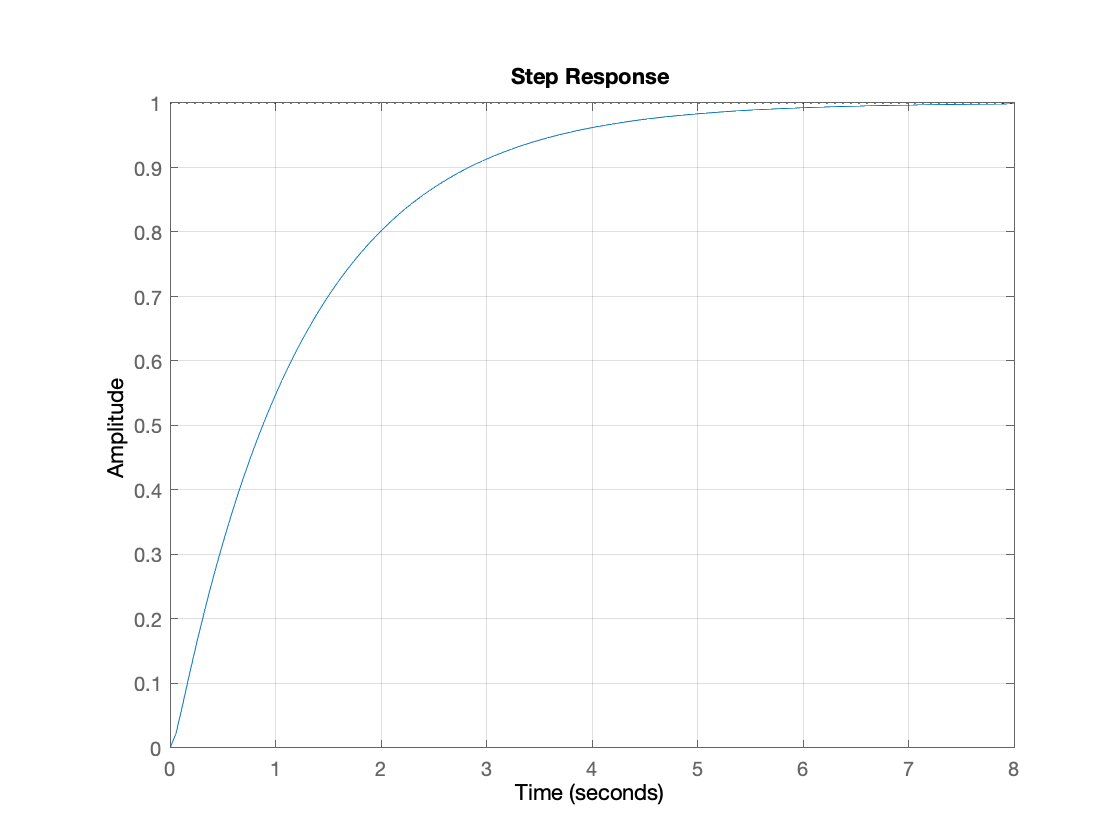

step(Gmf);
grid;

Tsmf = 4/14.04

Tsmf = 0.2849

## Projeto de um controlador PI

Função de transferência do controlador PI:


$$G_c(s) = K_p \frac{s+z_c}{s}$$


Desempenho: deseja-se posicionar oo polos dominantes  de malha fechada em:

$P_{1,2}=-40 \pm j40$ que implica em um tempo de acomodação estimado em $T_s = 0.1 s$

## Lugar das raizes do problema

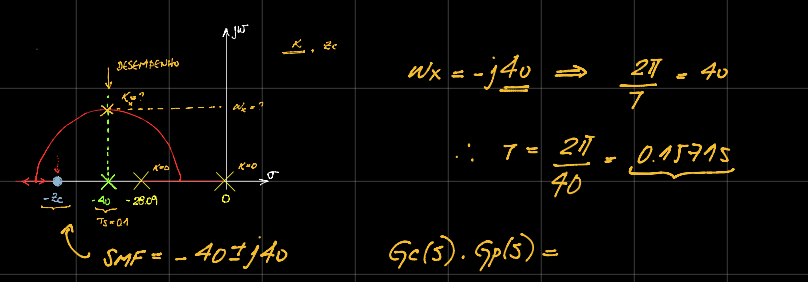

## Diagrama final do problema

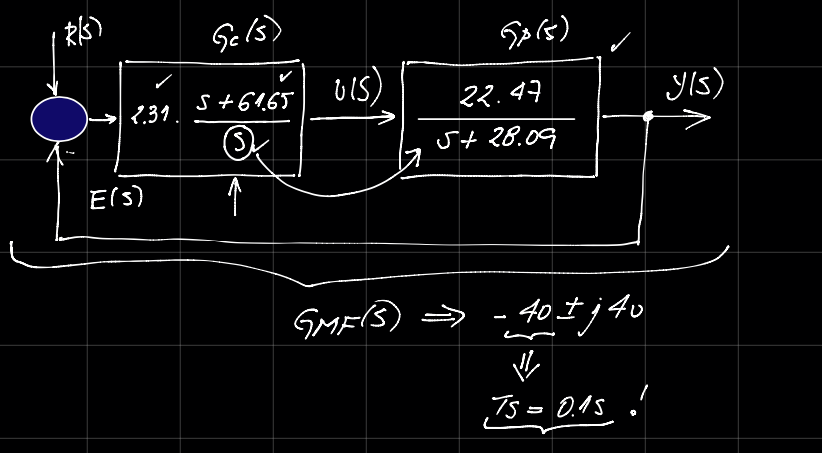

## Traduzindo para linguagem Matlab

Gc = tf(2.31*[1 61.65],[1 0]);
Gma = Gc*Gp;
Gmf = feedback(Gma,1)

Gmf =
 
   51.91 s + 3200
  -----------------
  s^2 + 80 s + 3200
 
Continuous-time transfer function.



## Polos em malha fechada

aux = cell2mat(Gmf.Denominator)

aux = 	1.0e+03 *

    0.0010    0.0800    3.2004


polos = roots(aux)

polos =  -40.0006 +40.0048i
 -40.0006 -40.0048i
